% Reading the cello and trombone sounds
%soundsc(cello.x, 1/cello.dt);
%soundsc(trombone.x, 1/trombone.dt);

%Calculating the number of samples in cello and trombone
Nc = length(cello.x)

Nc = 9288

Nt = length(trombone.x)

Nt = 9288


%Calculating the time of each instrument
Tc = Nc * cello.dt

Tc = 1.1338

Tt = Nt * trombone.dt

Tt = 1.1338


fprintf('Length of Cello recording: %.4f seconds\n', Tc);

Length of Cello recording: 1.1338 seconds


fprintf('Length of Trombone recording: %.4f seconds\n', Tt);

Length of Trombone recording: 1.1338 seconds


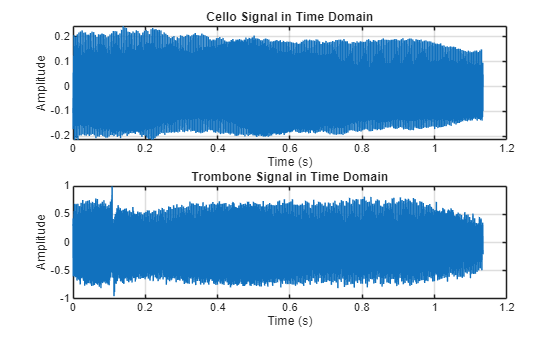

%% Part 2: Frequency Content Analysis
% Plotting the signals in Time Domain
figure('Name', 'Time Domain Signals');
subplot(2,1,1);
plot((0:Nc-1) * cello.dt, cello.x);
title('Cello Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');grid on;
subplot(2,1,2);
plot((0:Nt-1) * trombone.dt, trombone.x);
title('Trombone Signal in Time Domain');
xlabel('Time (s)'); ylabel('Amplitude');grid on;

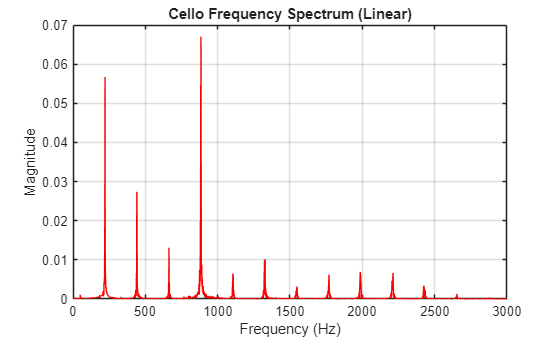

% --- Cello FFT ---
% Calculating the Sampling frequency
Fs_cello = 1 / cello.dt;       

%Creating a frequency vector for x axis 
f_cello = Fs_cello * (0:(Nc/2)) / Nc;

% Computing FFT(Fast Fourier Transform)
Y_cello = fft(cello.x);               

%Normalizing the signal and considering magnitude of the signal
P2_cello = abs(Y_cello / Nc);           

%Converting the two sided signal into a single sided signal and making sure
%that the energy if the signal is conserved
P1_cello = P2_cello(1:Nc/2+1);          
P1_cello(2:end-1) = 2 * P1_cello(2:end-1); 

% --- Trombone FFT ---
% Calculating the Sampling frequency
Fs_trombone = 1 / trombone.dt;     

%Creating a frequency vector for x axis 
f_trombone = Fs_trombone * (0:(Nt/2)) / Nt; 

% Computing FFT(Fast Fourier Transform)
Y_trombone = fft(trombone.x);    

%Normalizing the signal and considering magnitude of the signal
P2_trombone = abs(Y_trombone / Nt); 

%Converting the two sided signal into a single sided signal and making sure
%that the energy if the signal is conserved
P1_trombone = P2_trombone(1:Nt/2+1); 
P1_trombone(2:end-1) = 2 * P1_trombone(2:end-1);

% --- Plotting Cello (Linear & Logarithmic) ---
figure('Name', 'Cello Frequency Spectrum');
plot(f_cello, P1_cello, 'r');
title('Cello Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]);% Zoom in to see the peaks clearly
grid on;

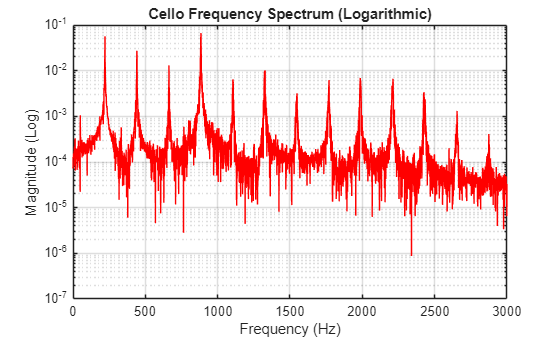


figure;
semilogy(f_cello, P1_cello, 'r');
title('Cello Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);
grid on;

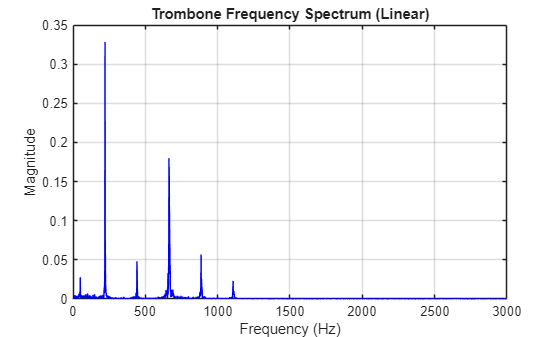



% --- Plotting Trombone (Linear & Logarithmic) ---
figure('Name', 'Trombone Frequency Spectrum');
plot(f_trombone, P1_trombone,'blue');
title('Trombone Frequency Spectrum (Linear)');
xlabel('Frequency (Hz)'); ylabel('Magnitude');
xlim([0 3000]);
grid on;

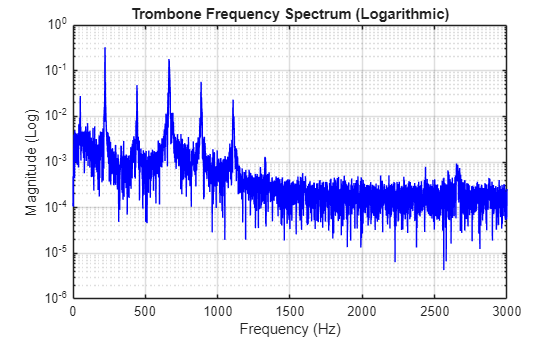


figure
semilogy(f_trombone, P1_trombone, 'blue');
title('Trombone Frequency Spectrum (Logarithmic)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Log)');
xlim([0 3000]);
grid on;

[peaks_mag, peak_freqs] = findpeaks(P1_trombone, f_trombone, ...
                                    'MinPeakHeight', 0.005, ... 
                                    'MinPeakDistance', 100);

fprintf('\n--- Trombone Peak Frequencies ---\n');


--- Trombone Peak Frequencies ---


% Display the first 6 peaks (The keynote + 5 overtones)
for i = 1:min(10, length(peak_freqs))
    fprintf('Peak %d: %.2f Hz\n', i, peak_freqs(i));
end

Peak 1: 50.27 Hz
Peak 2: 221.38 Hz
Peak 3: 441.88 Hz
Peak 4: 663.26 Hz
Peak 5: 885.53 Hz
Peak 6: 1106.91 Hz


[peaks_mag_C, peak_freqs_C] = findpeaks(P1_cello, f_cello, ...
                                    'MinPeakHeight', 0.005, ... 
                                    'MinPeakDistance', 100);

fprintf('\n--- Trombone Peak Frequencies ---\n');


--- Trombone Peak Frequencies ---


% Display the first 6 peaks (The keynote + 5 overtones)
for i = 1:min(12, length(peak_freqs_C))
    fprintf('Peak %d: %.2f Hz\n', i, peak_freqs_C(i));
end

Peak 1: 221.38 Hz
Peak 2: 441.88 Hz
Peak 3: 663.26 Hz
Peak 4: 884.64 Hz
Peak 5: 1105.14 Hz
Peak 6: 1328.29 Hz
Peak 7: 1770.17 Hz
Peak 8: 1985.38 Hz
Peak 9: 2212.05 Hz


%% Part 3: Signal Corruption and Recovery

% ==========================================
% 6. CELLO CORRUPTION & PARTIAL RECOVERY
% ==========================================
% Formula: CelloCorrupted[n] = n * cello[2n + 1] + 5

N_cello_max = floor((length(cello.x) - 1) / 2); 
cello_corrupted = zeros(N_cello_max, 1);

% 6a. Simulate corruption
for n = 1:N_cello_max
    cello_corrupted(n) = n * cello.x(2*n + 1) + 5;
end

% 6b & 6c. Cello Partial Recovery 
cello_recovered_partial = zeros(N_cello_max, 1);
for n = 1:N_cello_max
    cello_recovered_partial(n) = (cello_corrupted(n) - 5) / n;
end

% --- VISUALIZATION: Reconstructing the timeline ---
% Map the recovered odd samples back to their original timeline positions.
% The lost even samples will remain as 0.
cello_full_timeline = zeros(length(cello.x), 1);
for n = 1:N_cello_max
    cello_full_timeline(2*n + 1) = cello_recovered_partial(n);
end

% Plotting Original vs. Partially Recovered Cello (using stem for discrete visibility)
figure('Name', 'Cello Partial Recovery Verification');
% Plotting only the first 40 samples to make the discrete points visible
stem(1:100, cello.x(1:100), 'b','marker', 'none'); hold on;
stem(1:100, cello_full_timeline(1:100), 'rx', 'marker', 'none','LineWidth', 1.5);
legend('Original Signal', 'Recovered Signal (Zeros at lost indices)');
title('Cello Partial Recovery: Demonstration of Lost Samples');33

ans = 33

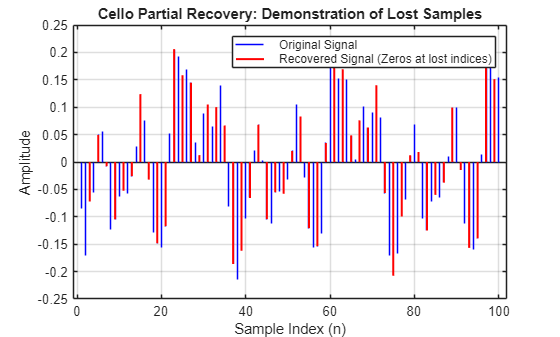

xlabel('Sample Index (n)'); ylabel('Amplitude');grid on
hold off;

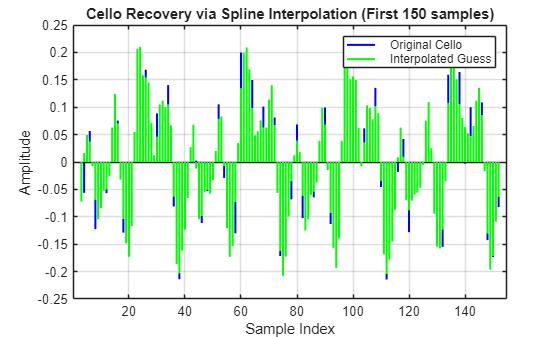

% ==========================================
% 6d. CELLO RECONSTRUCTION (INTERPOLATION)
% ==========================================

% 1. Define the original time indices we actually know
% The formula used 2n+1. So for n=1, index is 3. For n=2, index is 5, etc.
known_indices = (2 * (1:N_cello_max) + 1)'; 
known_values = cello_recovered_partial;

% 2. Define the full range of indices we want to guess/reconstruct
% We will reconstruct from the first known index (3) to the last known index.
query_indices = (3:known_indices(end))';

% 3. Perform the interpolation
% We use 'spline' (cubic spline) as it creates a smoother curve for audio 
% compared to 'linear' (which just draws straight lines between points).
cello_interpolated = interp1(known_indices, known_values, query_indices, 'spline');

% --- VISUALIZATION: Did it work? ---
figure('Name', 'Cello Interpolation Result');
% Plot the original signal (shifted to match our query range)
stem(query_indices(1:150), cello.x(query_indices(1:150)), 'b','marker', 'none', 'LineWidth', 1.5); hold on;
% Plot our interpolated guess
stem(query_indices(1:150), cello_interpolated(1:150), 'g','marker', 'none', 'LineWidth', 1.5);
legend('Original Cello', 'Interpolated Guess');
title('Cello Recovery via Spline Interpolation (First 150 samples)');
xlabel('Sample Index'); ylabel('Amplitude'); grid on;
hold off;

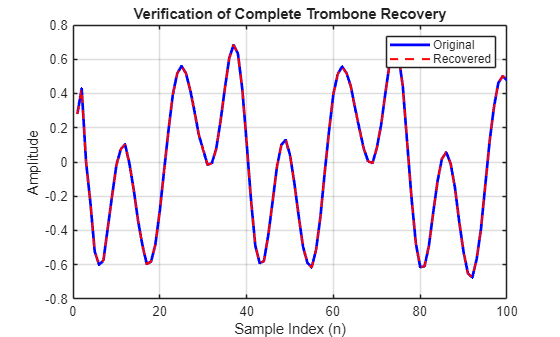



% ==========================================
% 7. TROMBONE CORRUPTION & FULL RECOVERY
% ==========================================
% Formula: TromboneCorrupted[n] = 0.5 * (trombone[n] + trombone[n-1])

trombone_corrupted = zeros(length(trombone.x), 1);

% 7a. Simulate corruption
trombone_corrupted(1) = 0.5 * trombone.x(1); 
for n = 2:length(trombone.x)
    trombone_corrupted(n) = 0.5 * (trombone.x(n) + trombone.x(n-1));
end

% 7b & 7c. Trombone Recovery
trombone_recovered = zeros(length(trombone_corrupted), 1);
trombone_recovered(1) = 2 * trombone_corrupted(1); 

for n = 2:length(trombone_corrupted)
    trombone_recovered(n) = 2 * trombone_corrupted(n) - trombone_recovered(n-1);
end

% Verify recovery success
figure('Name', 'Trombone Recovery Verification');
plot(1:100, trombone.x(1:100), 'b', 'LineWidth', 2); hold on;
plot(1:100, trombone_recovered(1:100), 'r--', 'LineWidth', 1.5);
legend('Original', 'Recovered');
title('Verification of Complete Trombone Recovery');
xlabel('Sample Index (n)'); ylabel('Amplitude');grid on;
hold off; 